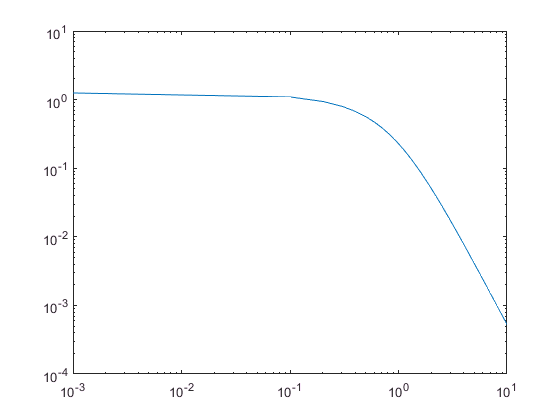

z = linspace(1e-3,1e1,100);
for i = 1 : length (z)
    f = @(x) exp(-x*z(i)).*besselj(3/2, x).*x.^.5;
    y(i) = integral(f,0,inf);
end
loglog(z,y)

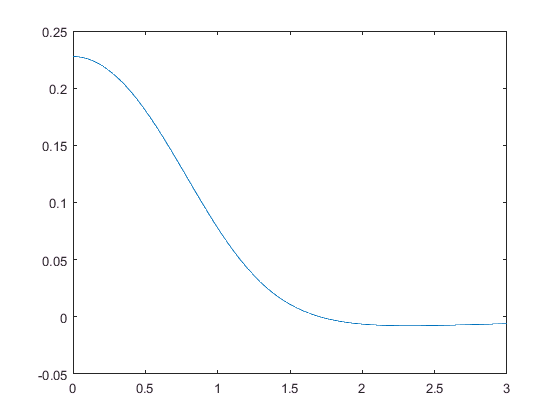

clear z
z = 1;
nu = 3/2;
rho = linspace(0,3,500);
a = 0;
for i = 1 : length (rho)
    f = @(x)exp(-x.*z).*besselj(0,rho(i).*x).*besselj(nu,1.*x).*x.^.5;
    yy(i) = integral(f,a,inf);
end
plot(rho,(yy))

% clear all
% f = 10e9;
% omega = 2*pi*f;
% ep1 = 1;
% ep2 = 10 - 1i*18;
% mu = 4*pi*1e-7;
% ep0 = 8.852e-12;
% k1 = omega*sqrt(mu*ep0*ep1);
% k2 = omega*sqrt(mu*ep0*ep2);
% kz1 = @(kp) sqrt(k1^2 - kp.^2);
% kz2 = @(kp) sqrt(k2^2 - kp.^2);
% gamma_1h = @(kp) (-kz2(kp) + kz1(kp))./(kz2(kp) +kz1(kp));
% gamma_1e = @(kp) (-kz2(kp)/ep2 + kz1(kp))./(kz2(kp)/ep2 +kz1(kp));
% G_1 = @(kp) k1./(1i*kz1(kp)).*(gamma_1h(kp));
% p = linspace(1e-3/k1,1e1/k1,500);
% a = 2*k1;
% 
% nu = 0;
% for i = 1 : length (p)
%     f = @(kp) G_1(kp).*besselj(nu, p(i)*kp).*kp;
%     yy(i) = integral(f,a,1e5,'AbsTol',1e-12,'RelTol',1e-12);
% end
% loglog(k1*p,abs(yy)/k1)

